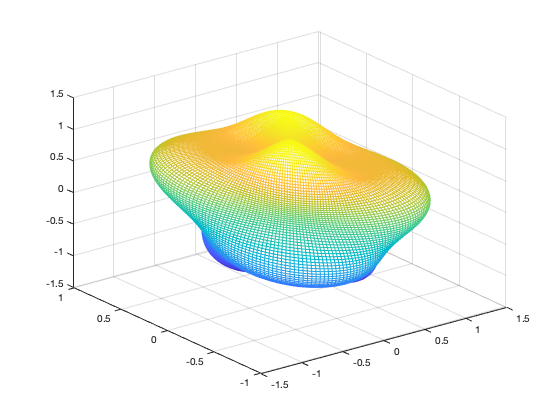

clc,clear
close all
m=4;
n=2;
theta=0:pi/100:pi;
phi=0:pi/100:2*pi;
[T,P]=meshgrid(theta,phi);
r=1+((1/5).*sin(m*T).*sin(n*P));
x=r.*sin(T).*cos(P);
y=r.*sin(T).*sin(P);
z=r.*cos(T);

mesh(x,y,z)


T=sym('T');
F=sym('F');
r=sym('r');
R=1+(1/5)*sin(m*T).*sin(n*F);
I1=int(r^2,0,R);
I1=simplify(I1);
I2=int(I1*sin(T),0,pi);
I2=simplify(I2);
I=int(I2,0,2*pi);
Volumen = double(I)

Volumen = 4.3164